# Critical Points of Functions of Two variables

## Introduction

One of the main uses of ordinary derivatives is in finding maximum and minimum values (extreme values). 

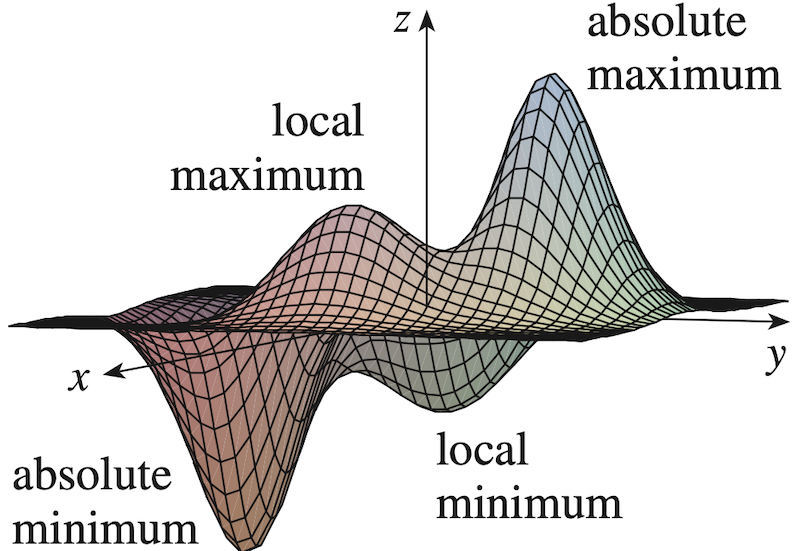

In this activity we will see how to use partial derivatives to locate maxima and minima of functions of two variables with the help of MATLAB.

## **Before starting**

Use the **MATLAB** **Live Editor** to **edit** and **run** this **Live Script** in your browser or your desktop.

- Read each section carefully. 

- Run the code within a section before starting to read the next. 

- To run the code from each section, *click into the code section* and then click on the **Run Section** button (from the toolstrip) or click on the blue stripe on left side of that section as shown below:

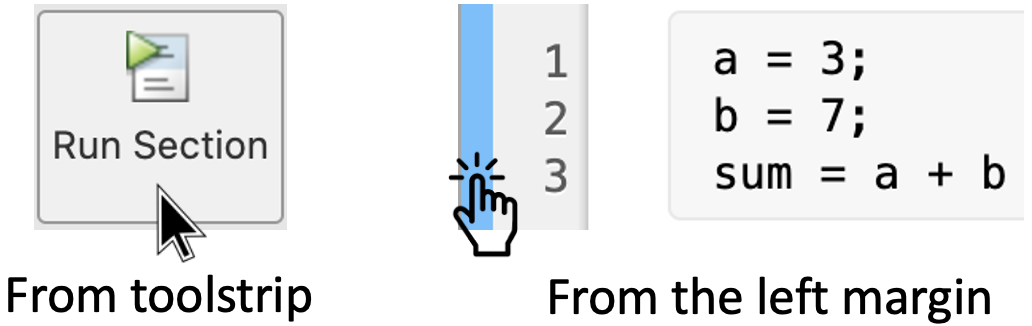

**Remark:** Run the code of each section from top to bottom, otherwise you may get an error.

- *The end of a section is indicated with a thin line, like the next one* -

## 1. Critical points for $f(x,y)$

Recall the definition of local maxima and local minima:

- $f(x,y)$ has a *local maximum* at $(a,b)$ if $f(a,b)\geq f(x,y)$ for all $(x,y$ sufficiently close to $(a,b)$.

- $f(x,y)$ has a *local minimum* at $(a,b)$ if $f(a,b)\leq f(x,y)$ for all $(x,y$ sufficiently close to $(a,b)$.

If $f$ is differentiable, a local maximum or minimum can only occur in points where the corresponding tangent plane is horizontal, i.e., where


$$\nabla f = \frac{\partial f}{\partial x}\mathbf i+ \frac{\partial f}{\partial y}\mathbf j = \mathbf 0.$$


**Remark:** If either one of $\frac{\partial f}{\partial x}$ or $\frac{\partial f}{\partial y}$ is undefined then $\nabla f$ is undefined. 

Finally, recall that a *critical point *of $f(x,y)$ is a point where either $\nabla f=(0,0)$ or where $\nabla f$ is undefined.

#### **Example 1:** 

Consider the function $f(x,y) = x^2+3x+y^2$.  Find the critical points of $f$.

**Step 1 -** To find the critical points in MATLAB first we need to define our function [symbolically](https://au.mathworks.com/help/symbolic/syms.html). That is:

**Step 2 -** Now we need to compute the partial derivatives using the command [`diff()`](https://au.mathworks.com/help/symbolic/diff.html) as follows:

**Step 3 -** Finally we solve the system of equations


$$\left\{
\begin{array}{rcl}
\frac{\partial f}{\partial x} & = &  0\\
\frac{\partial f}{\partial y} & = &  0
\end{array}
\right.$$


using the command [`solve()`](https://au.mathworks.com/help/symbolic/solve.html) and we will store the information in an array:

Thus, the complete MATLAB code is:

syms x y;
f = x^2 + 4 * x + y^2;
fx = diff(f, x);
fy = diff(f, y);
[xcr, yxr] = solve(fx, fy)

Run this section to see the output. Then find the critical point in your notebook and compare it with the result obtained in MATLAB.

## 2. Classification of critical points for $f(x,y)$

### 2.1 Second derivative test

Recall that we can classify critical points using the second-derivative test:

**Theorem: **Assume that $f$ and its first- and second-order partial derivatives are all continuous at $(a,b)$ and $\nabla f(a,b)=(0,0)$. Define the 2x2 determinant

$D = 
\displaystyle \left|
\begin{array}{cc}
\;f_{xx}(a,b) & f_{xy}(a,b)\; \\
\;f_{yx}(a,b) & f_{yy}(a,b)\; \\
\end{array}
\right|$.

Then:

- $f_{xx}(a, b) > 0$ and $D > 0$ implies that $(a, b)$ is a *local minimum*;

- $f_{xx}(a, b) < 0$ and $D > 0$ implies that $(a, b)$  is a* local maximum*; 

- $D < 0$ implies that $(a, b)$ is a *saddle point*;

- if $D = 0$ the second-derivative test is *inconclusive*.

For example, the function

$f(x,y) = 3x^2y+y^3-6xy-2$               (1)

has four critical points $(0,0), (1,1), (1,-1)$, and $(2,0)$. They are classified as follows:

- $(1,1)$ is a local minimum,

- $(1,-1)$ is a local maximum, and

- $(0,0)$ and $(2,0)$ are both saddle points.

You can confirm this in your notebook or use the MATLAB code in section 1.

### 2.2 Classification of critical points in MATLAB

In order to classify critical points in MATLAB we are going to use the pre-defined function named

`ClassifyCP(f, var1, var2, xcp, ycp)`

which is defined in the Appendix. This is a function that can determine if a critical point is a local maximum, a local minimum, or a saddle point. The parameters we need to input (as strings) are:

- `f`: The function `f(x,y)` or `f(u,v)`

- `var1`: The first variable `x/u`

- `var2:` The second variable `y/v`

- `xcp`: The x-coordinate of the critical point to classify

- `ycp`: The y-coordinate of the critical point to classify

For instance, using the function defined in (1) considering the critical point (1,1) we write:

ClassifyCP('3 * x^2 * y + y^3 - 6 * x * y - 2', 'x', 'y', 1, 1)

For the critical point (1,-1):

ClassifyCP('3 * x^2 * y + y^3 - 6 * x * y - 2', 'x', 'y', 1, -1)

For the critical point (0,0):

ClassifyCP('3 * x^2 * y + y^3 - 6 * x * y - 2', 'x', 'y', 0, 0)

And for the critical point (2,0):

ClassifyCP('3 * x^2 * y + y^3 - 6 * x * y - 2', 'x', 'y', 2, 0)

Run this section to see the outputs and compare with the results in section 2.1. 

## 3. Hands on practice

#### **Activity 1: **

Find the critical points of the following functions:

- 
$$f(x,y)=(x-y)\exp(-x^2-y^2)$$


- 
$$g(u,v)=\left(u^2+u^2\right)\exp(-u)$$


- 
$$h(x,y)=x^4+y^3-3x^2+y^2+x-2y+1$$


Use the code in section 1. Write your code here:

**Challenge:** Try to write your own [MATLAB function](https://au.mathworks.com/help/matlab/ref/function.html) to find critical points for any function of two variables. You can add it at the of the Appendix. Your MATLAB function **should take any arbitrary function** `f` as an input. You can **set the output** of your MATLAB function to be the horizontal concatenation of `xcr` and `ycr`, see example in section 1.

#### **Activity 2:**

Find the critical points of the function

$f(x,y)=xy\exp\left(\frac{-x^2-y^2}{2}\right)$.

You can do this in your notebook, or with MATLAB (maybe using your own function from Activity 1, if you wrote one).

Use the pre-defined function `ClassifyCP(f, var1, var2, xcp, ycp)` to classify the critical points of this function.

Write your code here:

## Appendix: Pre-defined functions

function [ output ] = ClassifyCP(f, var1, var2, xcp, ycp)
% CLASSIFYCP is a function that can classify critical points
% Example:
% >> ClassifyCP('-(x^2-1)^2-(x^2*y-x-1)^2','x', 'y',-1,0)
%
% ans =
% The critical point (x,y)=(-1,0) is a local maximum

% Define symbolic function
f = str2sym(f);

% Convert variables into symbolic variables.
var1 = sym(var1);
var2 = sym(var2);
 
% Calculate the first and second order partial derivatives
fx = diff(f, var1);
fy = diff(f, var2);
fxx = diff(fx, var1);
fxy = diff(fx, var2);
fyy = diff(fy, var2);
 
% Calculate Discriminant and 2nd order partials by
% subbing in critical point with subs()
D = fxx * fyy - fxy^2;
D = simplify(D);
Dval = subs(D, {var1,var2}, [xcp,ycp]);
fxxval = subs(fxx, {var1,var2}, [xcp,ycp]);
fyyval = subs(fyy, {var1,var2}, [xcp,ycp]);
 
% Classify the critical point
if Dval > 0 && (fxxval < 0 || fyyval < 0)
    classtext= 'local maximum';
elseif Dval > 0 && (fxxval > 0 || fyyval > 0)
    classtext= 'local minimum';
elseif Dval < 0
    classtext= 'saddle point';
else
    classtext= 'unable to be categorised';
end

output = ['The critical point (x,y) = (',...
          num2str(xcp),',',...
          num2str(ycp),')']; 
output = [output newline ' is a ', classtext];
end

% Documentation for the commands used in this function:
% https://au.mathworks.com/help/symbolic/str2sym.html
% https://au.mathworks.com/help/symbolic/sym.html
% https://au.mathworks.com/help/symbolic/diff.html
% https://au.mathworks.com/help/symbolic/simplify.html
% https://au.mathworks.com/help/symbolic/subs.html
% https://au.mathworks.com/help/matlab/ref/num2str.html


% ---- Write your own functions after this line ---- %


% Write a function to calculate the critical points of f
% The Output is an array cr = [xcr, ycr] where xcr and ycr
% are respectively column vectors of the x-coordinates
% and y-coordinates of the critical points.
% https://au.mathworks.com/help/matlab/ref/function.html
 
% Step 1 - Convert f from text string to a symbolic expression.

 
% Step 2 - Convert variables into symbolic variables.

 
% Step 3 - Calculate Partials.

 
% Step 4 - Solve for critical point and return the value.

